clear
clc
clf
%Problem 2
%To find
%TSFC
%Specific thrust
%Thermal efficiency
%Propulsive efficiency
%Overall efficiency
%pi_c = 1 to 24
%Turbojet with afterburner
%Input parameters with afterburner

M_o = 2.0;
P_o = 10000; %Static pressure(Pa)
T_o = 228.15; %Static temperature(K)
R = 287;
gamma = 1.4;
cp = 1004; %(J/kg.K)
%pi_c (P_o3/P_o2) (To vary from 1 to 24)
T_oa = T_o * (1 + ((gamma-1)/2)*(M_o)^2);
tow_lambda = 8; %((Cpt * T_o4)/(Cpc * T_o))
delH = 43 * 10^6; %Heating value (J/kg)
tow_lambda_AB = 11; %Temperature ratio of afterburner (T_o7/T_o)
a_o = sqrt(gamma * R * T_o);
V_o = M_o * a_o;
T_t4 = (tow_lambda)*T_o; %Burner exit temperature
T_t7 = (tow_lambda_AB)*(T_o); %Total temperature at exit of afterburner
P_to = P_o*((1+((gamma-1)/2)*(M_o)^2)^((gamma)/(gamma-1)));
T_to = T_o*(1+((gamma-1)/2)*(M_o)^2);
T_t2 = T_to;
P_t2 = P_to;
tow_r = 1 + (((gamma-1)/2)*(M_o)^2);

y = 1;

for pi_c = (1:24)
P_t3(1,y) = P_t2 * pi_c;
tow_c(1,y) = (pi_c)^((gamma-1)/gamma); %Compressor temperature ratio
T_t3 = T_t2 .* tow_c;
P_t4 = P_t3;
f = (cp .* (T_t4 - T_t3))./(delH - (cp * T_t4));
T_t5 = T_t4 - ((T_t3 - T_t2)/(1+f));
pi_t = (T_t5/T_t4)^((gamma)/(gamma-1));
P_t5 = P_t4 * pi_t;
P_t7 = P_t5;
f_ab = ((1+f)*((cp * T_t7)-(cp * T_t5)))/((delH - (cp * T_t7)));
P_t9 = P_t7;
T_t9 = T_t7;
P_9 = P_o;
M_9 = sqrt((2/(gamma-1))*(((P_t9/P_9).^((gamma-1)/(gamma))) - 1));
T_9 = T_t9./(1 + ((gamma-1)/2)*((M_9).^2));
a_9 = sqrt(gamma * R * T_9);
V_9 = M_9.*a_9;
specific_thrust = ((1+f+f_ab).*V_9) - V_o;
non_specific_thrust = ((1+f+f_ab).*(V_9/a_o)) - M_o;
TSFC = (f+f_ab)./(specific_thrust);
A = ((1+f+f_ab).*((V_9).^2)/2) - ((V_o).^2/2);
B = (f + f_ab).* delH;
Thermal_eff = (A./B);
Propulsive_eff = ((specific_thrust * V_o)./A);
Overall_eff = Thermal_eff .* Propulsive_eff;
y = y+1;
end

x = (1:24);

non_specific_thrust;
TSFC;
Thermal_eff;
Propulsive_eff;
Overall_eff;

clc
clf
%Problem 2
%To find
%TSFC
%Specific thrust
%Thermal efficiency
%Propulsive efficiency
%Overall efficiency
%pi_c = 1 to 24

%Input parameters
%Turbojet without afterburner

M_o = 2.0;
P_o = 10000; %Static pressure(Pa)
T_o = 228.15; %Static temperature(K)
R = 287;
gamma = 1.4;
cp = 1004; %(J/kg.K)
%pi_c (P_o3/P_o2) (To vary from 1 to 24)
T_oa = T_o * (1 + ((gamma-1)/2)*(M_o)^2);
tow_lambda = 8; %((Cpt * T_o4)/(Cpc * T_o))
delH = 43 * 10^6; %Heating value (J/kg)
tow_lambda_AB = 11; %Temperature ratio of afterburner (T_o7/T_o)
a_o = sqrt(gamma * R * T_o);
V_o = M_o * a_o;
T_t4 = (tow_lambda)*T_o; %Burner exit temperature
T_t7 = (tow_lambda_AB)*(T_oa); %Total temperature at exit of afterburner
P_to = P_o*((1+((gamma-1)/2)*(M_o)^2)^((gamma)/(gamma-1)));
T_to = T_o*(1+((gamma-1)/2)*(M_o)^2);
T_t2 = T_to;
P_t2 = P_to;
tow_r = 1 + (((gamma-1)/2)*(M_o)^2);
y = 1;

for pi_c = (1:24)
P_t3(1,y) = P_t2 * pi_c;
tow_c(1,y) = (pi_c)^((gamma-1)/gamma); %Compressor temperature ratio
T_t3 = T_t2 .* tow_c;
P_t4 = P_t3;
f = (cp .* (T_t4 - T_t3))./(delH - (cp * T_t4));
T_t5 = T_t4 - ((T_t3 - T_t2)/(1+f));
pi_t = (T_t5/T_t4)^((gamma)/(gamma-1));
P_t5 = P_t4 * pi_t;
%P_t7 = P_t5;
%f_ab = ((1+f)*((cp * T_t7)-(cp * T_t5)))/((delH - (cp * T_t7)));
P_t9 = P_t5;
T_t9 = T_t5;
P_9 = P_o;
M_9 = sqrt((2/(gamma-1))*(((P_t9/P_9).^((gamma-1)/(gamma))) - 1));
T_9 = T_t9./(1 + ((gamma-1)/2)*((M_9).^2));
a_9 = sqrt(gamma * R * T_9);
V_9 = M_9.*a_9;
specific_thrust_i = ((1+f).*V_9) - V_o;
non_specific_thrust_i = ((1+f).*(V_9/a_o)) - M_o;
TSFC_i = (f)./(specific_thrust_i);
A = ((1+f).*((V_9).^2)/2) - ((V_o).^2/2);
B = (f).* delH;
Thermal_eff_i = (A./B);
%Propulsive_eff_i = ((specific_thrust_i * V_o)./A);
%Thermal_eff_i = 1 - (T_o./T_t3);
Propulsive_eff_i = 2./(1 + (V_9/V_o));
Overall_eff_i = Thermal_eff_i .* Propulsive_eff_i;
y = y+1;
end

%{
for pi_c = (1:24)
tow_c(1,y) = (pi_c)^((gamma-1)/gamma); %Compressor temperature ratio
tow_r = 1 + (((gamma-1)/2)*(M_o)^2);
tow_t = 1 - ((tow_r/tow_lambda)*(tow_c - 1));
vbya = sqrt((2/(gamma-1))*((tow_lambda)./(tow_r.*tow_c)).*((tow_r.*tow_c.*tow_t)-1));
specific_thrust_i = (a_o) * (vbya - M_o);
f_i = ((cp * T_o) * ((tow_lambda) - (tow_r * tow_c)))/(delH);
TSFC_i = f_i./(specific_thrust_i);
Thermal_eff_i = 1 - (1./(tow_r .* tow_c));
Propulsive_eff_i = (2 * M_o)./(vbya + M_o);
overall_eff_i = Thermal_eff_i .* Propulsive_eff_i;
y = y+1;
end
%}
x = (1:24);
specific_thrust_i;
TSFC_i;
Thermal_eff_i;
Propulsive_eff_i;
Overall_eff_i;

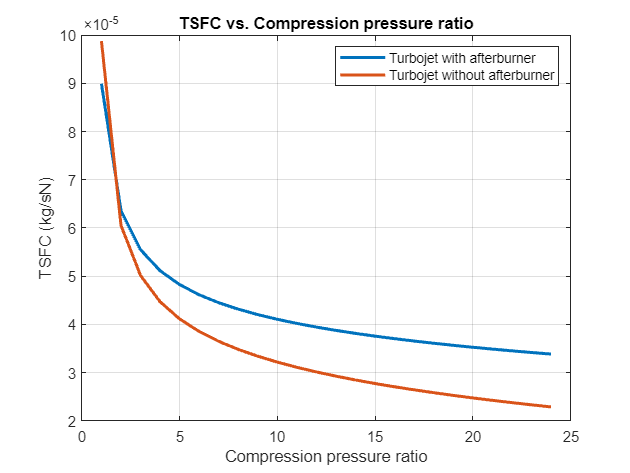

plot(x,TSFC,'LineWidth',2)
hold on 
plot(x,TSFC_i,'LineWidth',2)
xlabel('Compression pressure ratio');
ylabel('TSFC (kg/sN)');
title('TSFC vs. Compression pressure ratio');
legend('Turbojet with afterburner','Turbojet without afterburner')
grid on
hold off

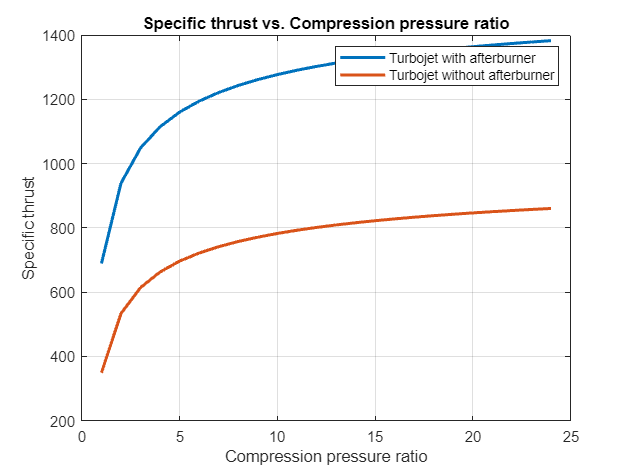


plot(x,specific_thrust,'LineWidth',2)
hold on 
plot(x,specific_thrust_i,'LineWidth',2)
xlabel('Compression pressure ratio');
ylabel('Specific thrust');
title('Specific thrust vs. Compression pressure ratio');
legend('Turbojet with afterburner','Turbojet without afterburner');
grid on
hold off

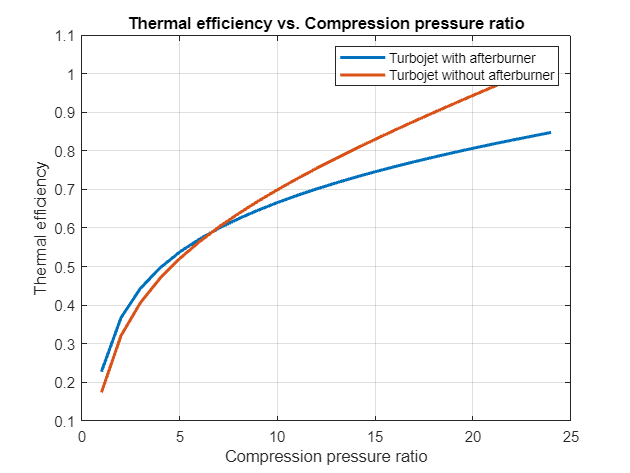


plot(x,Thermal_eff,'LineWidth',2)
hold on 
plot(x,Thermal_eff_i,'LineWidth',2)
xlabel('Compression pressure ratio');
ylabel('Thermal efficiency');
title('Thermal efficiency vs. Compression pressure ratio');
legend('Turbojet with afterburner','Turbojet without afterburner')
grid on
hold off

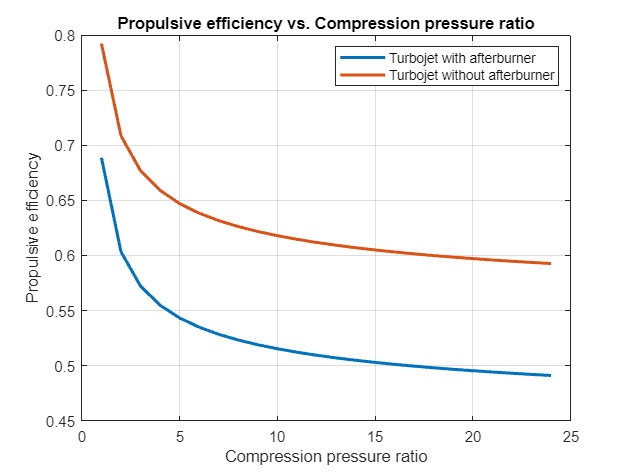


plot(x,Propulsive_eff,'LineWidth',2)
hold on 
plot(x,Propulsive_eff_i,'LineWidth',2)
xlabel('Compression pressure ratio');
ylabel('Propulsive efficiency');
title('Propulsive efficiency vs. Compression pressure ratio');
legend('Turbojet with afterburner','Turbojet without afterburner')
grid on
hold off

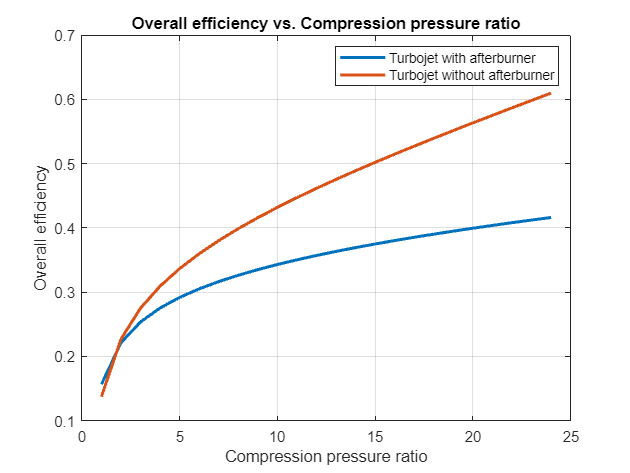


plot(x,Overall_eff,'LineWidth',2)
hold on 
plot(x,Overall_eff_i,'LineWidth',2)
xlabel('Compression pressure ratio');
ylabel('Overall efficiency');
title('Overall efficiency vs. Compression pressure ratio');
legend('Turbojet with afterburner','Turbojet without afterburner')
grid on
hold off